# Composition analysis using TGA (multiple run) 

2/22/2023 Nanta

## 1. Load data


clear variables

DTGdata_all = load('DTGdata_biomass.mat');

% Data and name
Data = ["PineExtFree_20Kpm_R1";"SwitchgrassExtFree_20Kpm_R2"];

Name = ["Pine Ext-free";"Swtichgrass Ext-free"];

% Other data
%{
Data = ["Pine20Kpm_R1","Pine20Kpm_R2","PineExtFree_20Kpm_R1","PineExtFree_20Kpm_R2",...
        "PP20Kpm_R4","PP20Kpm_R5","PPExtFree_20Kpm_R1","PPExtFree_20Kpm_R2","PPExtFree_20Kpm_R3",...
        "Birch_20Kpm_R1","Birch_20Kpm_R2", "BirchExtFree_20Kpm_R1","BirchExtFree_20Kpm_R2",...
        "Oak_20Kpm_R1","Oak_20Kpm_R2","OakExtFree_20Kpm_R1","OakExtFree_20Kpm_R2",...
        "BarkPine_20Kpm_R1","BarkPine_20Kpm_R2","BarkPineExtFree_20Kpm_R1","BarkPineExtFree_20Kpm_R2",...
        "Switchgrass_20Kpm_R1","Switchgrass_20Kpm_R2","SwitchgrassExtFree_20Kpm_R1","SwitchgrassExtFree_20Kpm_R2"];

samplename = ["Pine","Pine","Pine Ext-free","Pine Ext-free",...
              "Potato peel","Potato peel","Potato peel Ext-free","Potato peel Ext-free","Potato peel Ext-free",...
              "Birch","Birch","Birch Ext-free","Birch Ext-free",...
              "Oak","Oak","Oak Ext-free","Oak Ext-free",...
              "Bark","Bark","Bark Ext-free","Bark Ext-free",...
              "Swtichgrass","Swtichgrass","Swtichgrass Ext-free","Swtichgrass Ext-free"];
%}


## 2. Input Extractives and Ash(partial) data

%%% Input manually
%%% Extractives (wt%db) and ash (wt% extractive-free basis)

Ext = [4.6;23.4]

Ext =     4.6000
   23.4000


AshE = [0.11;2.9]

AshE =     0.1100
    2.9000


## 3. Fit with 3 curves 

beta = 20

    Run       Local       Local      Local    Local   First-order
   Index     exitflag      f(x)     # iter   F-count   optimality
       1         2      0.02523        81       834     1.782e-06

MultiStart completed the runs from all start points.

The local solver ran once and converged with a positive local solver exit flag.


bb_fm =    12.4266  246.0759    0.5366   11.6999  145.0650    0.2331   18.2503   31.5419    0.2063


fval_msfm = 0.0252

exitflag = 1

outputMS = struct with fields:
                funcCount: 844
         localSolverTotal: 1
       localSolverSuccess: 1
    localSolverIncomplete: 0
    localSolverNoSolution: 0
                  message: 'MultiStart completed the runs from all start points.↵↵The local solver ran once and converged with a positive local solver exit flag.'


solutions =   GlobalOptimSolution with properties:

           X: [12.4266 246.0759 0.5366 11.6999 145.0650 0.2331 18.2503 31.5419 0.2063]
        Fval: 0.0252
    Exitflag: 2
      Output: [1×1 struct]
          X0: {[11.9000 218 0.5000 11.1000 105.2000 0.3000 17.8000 53.5000 0.2000]}


fval_msfm = 0.0252

Rsq_msfm = 0.9986

T_peakC1 = 380.5602

T_peakC2 = 336.5946

T_peakC3 = 388.5516

figN = "./PineExtFree_20Kpm_R1_fit_3curves_23728.fig"

figN = "./PineExtFree_20Kpm_R1_fit_3curves_23728.png"

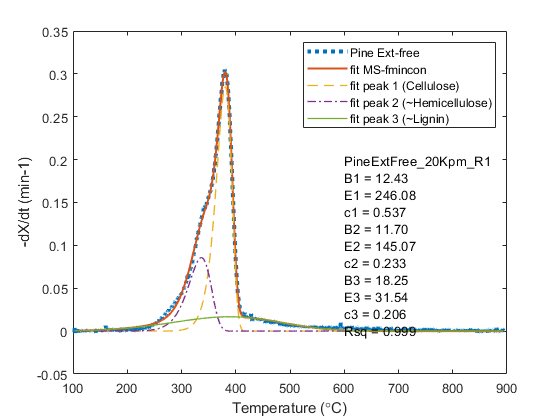

output =    12.4266  246.0759    0.5366   11.6999  145.0650    0.2331   18.2503   31.5419    0.2063    0.9986  380.5602  336.5946  388.5516    0.9800


FitResults3curves = struct with fields:
    PineExtFree_20Kpm_R1: [1×1 struct]


FitResults3curves = struct with fields:
    PineExtFree_20Kpm_R1: [1×1 struct]


FitResults3curves = struct with fields:
    PineExtFree_20Kpm_R1: [1×1 struct]


beta = 20

    Run       Local       Local      Local    Local   First-order
   Index     exitflag      f(x)     # iter   F-count   optimality
       1         1      0.03179        67       686      9.97e-07

MultiStart completed the runs from all start points.

The local solver ran once and converged with a positive local solver exit flag.


bb_fm =    12.2365  196.2937    0.4779   11.2256  154.8000    0.3445   16.3574   47.5525    0.1521


fval_msfm = 0.0318

exitflag = 1

outputMS = struct with fields:
                funcCount: 696
         localSolverTotal: 1
       localSolverSuccess: 1
    localSolverIncomplete: 0
    localSolverNoSolution: 0
                  message: 'MultiStart completed the runs from all start points.↵↵The local solver ran once and converged with a positive local solver exit flag.'


solutions =   GlobalOptimSolution with properties:

           X: [12.2365 196.2937 0.4779 11.2256 154.8000 0.3445 16.3574 47.5525 0.1521]
        Fval: 0.0318
    Exitflag: 1
      Output: [1×1 struct]
          X0: {[11.9000 218 0.5000 11.1000 105.2000 0.3000 17.8000 53.5000 0.2000]}


fval_msfm = 0.0318

Rsq_msfm = 0.9976

T_peakC1 = 368.3979

T_peakC2 = 314.5471

T_peakC3 = 428.3547

figN = "./SwitchgrassExtFree_20Kpm_R2_fit_3curves_23728.fig"

figN = "./SwitchgrassExtFree_20Kpm_R2_fit_3curves_23728.png"

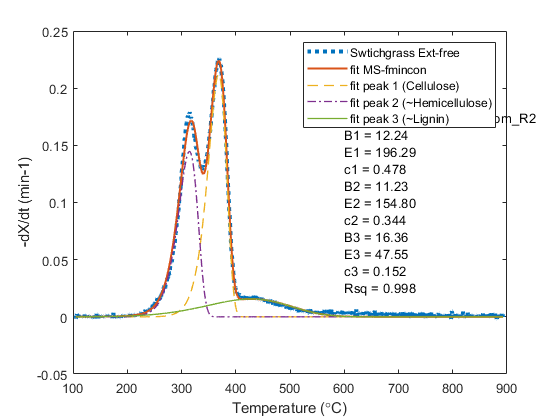

output =    12.2365  196.2937    0.4779   11.2256  154.8000    0.3445   16.3574   47.5525    0.1521    0.9976  368.3979  314.5471  428.3547    0.9709


FitResults3curves = struct with fields:
           PineExtFree_20Kpm_R1: [1×1 struct]
    SwitchgrassExtFree_20Kpm_R2: [1×1 struct]


FitResults3curves = struct with fields:
           PineExtFree_20Kpm_R1: [1×1 struct]
    SwitchgrassExtFree_20Kpm_R2: [1×1 struct]


FitResults3curves = struct with fields:
           PineExtFree_20Kpm_R1: [1×1 struct]
    SwitchgrassExtFree_20Kpm_R2: [1×1 struct]


% fit with 3 curves
for i=1:length(Data)
    [FitResults3curves.(Data(i)).output, FitResults3curves.(Data(i)).outputMS, FitResults3curves.(Data(i)).solutions] = DTG_fit_3curves_biomass_fnc(DTGdata_all.(Data(i)),Name(i),Data(i))    
end


%save('FitResults3curves.mat','FitResults3curves');

% Extracting results
output3curves = zeros(length(Data),14);
for i=1:length(Data)
    % output columns are
    % B1 E1 c1 B2 E2 c2 B3 E3 c3 Rsq_msfm T_peakC1 T_peakC2 T_peakC3 AreaFit/AreaExp   
    output3curves(i,:) = FitResults3curves.(Data(i)).output;

end

## or 3. Fit with 5 curves 

% fit with 5 curves
%{
for i=1:length(Data)
    [FitResults5curves.(Data(i)).output, FitResults5curves.(Data(i)).outputMS, FitResults5curves.(Data(i)).solutions] = DTG_fit_5curves_biomass_fnc(DTGdata_all.(Data(i)),Name(i),Data(i)) 
end

% Extracting results
output5curves = zeros(length(Data),22);
for i=1:length(Data)
    % output columns are
    % B1 E1 c1 B2 E2 c2 B3 E3 c3 B4 E4 c4 B5 E5 c5 Rsq_msfm T_peakC1 T_peakC2 T_peakC3 T_peakC4 T_peakC5 AreaFit/AreaExp
    output5curves(i,:) = FitResults5curves.(Data(i)).output;

end
%}

## 4. Calculate compositions

% For fit with 3 curves
Cell_percentdb = zeros(length(Data),1);
Hemi_percentdb = zeros(length(Data),1);
Lig_percentdb = zeros(length(Data),1);
Ash_db = zeros(length(Data),1);

for i=1:length(Data)
    [Cell_percentdb(i), Hemi_percentdb(i), Lig_percentdb(i),Ash_db(i)] = CalComp(3,output3curves(i,:),Ext(i),AshE(i));
end

Results = table(Data,Name,Cell_percentdb, Hemi_percentdb, Lig_percentdb,Ext,Ash_db)

Results = 2×7 table
                Data                          Name             Cell_percentdb    Hemi_percentdb    Lig_percentdb    Ext     Ash_db 
    _____________________________    ______________________    ______________    ______________    _____________    ____    _______

    "PineExtFree_20Kpm_R1"           "Pine Ext-free"               44.072             22.19           29.033         4.6    0.10494
    "SwitchgrassExtFree_20Kpm_R2"    "Swtichgrass Ext-free"        31.238            26.102           17.038        23.4     2.2214


## Function for calculating composition

Adjusting with char fraction, extractives, and ash

function [Cell_percentdb, Hemi_percentdb, Lig_percentdb, Ash_db] = CalComp(numcurvefit, fitoutput,Ext, AshE)

    % Caluclate ash (partial) dry basis
    Ash_db = AshE*(1-Ext/100);

    % Initial c from fitting
    if numcurvefit == 3
        c_Cell = fitoutput(3)*100;
        c_Hemi = fitoutput(6)*100;
        c_Lig = fitoutput(9)*100;
    elseif numcurvefit == 5
        c_Cell = fitoutput(3)*100;
        c_Hemi = (fitoutput(6) + fitoutput(9))*100;
        c_Lig  = (fitoutput(12)+ fitoutput(15))*100;  
    else
        disp('Wrong no. of curves used for fitting. Only 3 or 5 allow.')
        return 
    end
    
    % Reference char fraction of cellulose, hemicellulose and lignin
    % Please see paper for references
    Cell_char_ref = 7.26;
    Hemi_char_ref = 20.0;
    Lig_char_ref = 45.87;
    
    % Adjust with char fraction
    c_Cell_charadj = c_Cell/(100-Cell_char_ref);
    c_Hemi_charadj = c_Hemi/(100-Hemi_char_ref);
    c_Lig_charadj = c_Lig/(100-Lig_char_ref);
    
    sum_c =  c_Cell_charadj + c_Hemi_charadj + c_Lig_charadj;

    % normalize, and adjust with extractives and ash content
    Cell_percentdb = c_Cell_charadj*(100-Ext-Ash_db)/sum_c;
    Hemi_percentdb = c_Hemi_charadj*(100-Ext-Ash_db)/sum_c;
    Lig_percentdb = c_Lig_charadj*(100-Ext-Ash_db)/sum_c;

    %Composition_db = [Cell_percentdb Hemi_percentdb Lig_percentdb Ext Ash_db]
end
